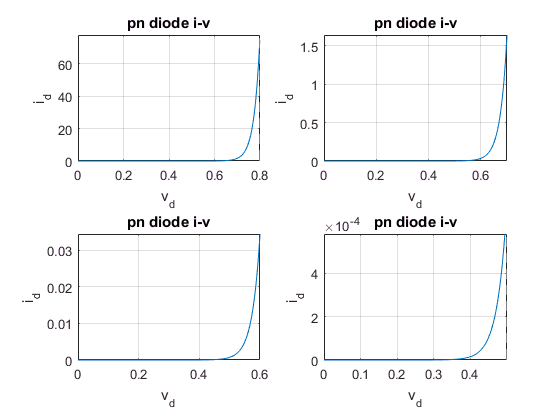

%{
Plot Ideal Diode I-V curves on different scales to illustrate their 
"fractal" nature, i.e. they look the same no matter how much they're
zoomed in. Therefore the diode's turn-on voltage is a matter of scale.
%}



Is = 3e-12; % pn diode saturation current.
VT = 0.0259; % Thermal voltage at 300K.
id = @(vd) Is*(exp(vd/VT) - 1); % Ideal diode equation.
%
% The diode's turn-on voltage is a matter of scale:
subplot(2,2,1), fplot(id, [0,0.8]), title('pn diode i-v'), ylabel('i_d'), xlabel('v_d'), grid ON; 
subplot(2,2,2), fplot(id, [0,0.7]), title('pn diode i-v'), ylabel('i_d'), xlabel('v_d'), grid ON; 
subplot(2,2,3), fplot(id, [0,0.6]), title('pn diode i-v'), ylabel('i_d'), xlabel('v_d'), grid ON; 
subplot(2,2,4), fplot(id, [0,0.5]), title('pn diode i-v'), ylabel('i_d'), xlabel('v_d'), grid ON; 